# Chapter 1, Section 2 (Part 4)

The goal in this activity is to introduce what is known as a reduced row echelon form of a matrix. 

**Row Echelon Form: A rectangular matrix is in row echelon form if it has the following three properties:**

**1. All nonzero rows are above any rows of all zeros.**

**2. Each leading entry of a row is in a column to the right of the leading entry of the row above it.**

**3. All entries in a column below a leading entry are zeros.**

Now, a reduced row echelon form of a matrix also obeys properties 1, 2, and 3, but in addition:

**4: Each leading term in each row is a 1.**

**5. All entries above and below the leading term are zero.**

Let's do an example.

# Example #1:

Solve the following system for $x$, $y$, and $z$.


$$\begin{array}{rcl}
x+y&=&-1\\
y-z&=&-7\\
x-3y+2z&=&19
\end{array}$$


**Solution:** Let's rewrite the system to make the augmented matrix more clear.


$$\begin{array}{rcl}
1x+1y+0z&=&-1\\
0x+1y-1z&=&-7\\
1x-3y+2z&=&19
\end{array}$$


Let's write our augmented matrix and highlight the leading entry in row one.


$$\pmatrix{[1] & 1 & 0 & -1\cr 0 & 1 & -1 & -7\cr1 & -3 & 2 & 19}$$


Let's zero out the entries below the highlighted leading term in row one.


$$\pmatrix{[1] & 1 & 0 & -1\cr 0 & 1 & -1 & -7\cr1 & -3 & 2 & 19}\ \matrix{~\cr ~\cr R_3-R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 0 & -1\cr 0 & 1 & -1 & -7\cr 0 & -4 & 2 & 20}$$


Let's check this step with Matlab.

A=[1 1 0 -1;0 1 -1 -7;1 -3 2 19];
r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2;r3-r1]

A =      1     1     0    -1
     0     1    -1    -7
     0    -4     2    20


We are correct thus far. Now we will highlight the leading term in row two and zero out all entries below it.


$$\pmatrix{1 & 1 & 0 & -1\cr 0 & [1] & -1 & -7\cr 0 & -4 & 2 & 20}\ \matrix{~\cr ~\cr R_3+4R_2}\qquad\longrightarrow\qquad \pmatrix{1 & 1 & 0 & -1\cr 0 & 1 & -1 & -7\cr 0 & 0 & -2 & -8}$$


Let's check this step in Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2;r3+4*r2]

A =      1     1     0    -1
     0     1    -1    -7
     0     0    -2    -8


Correct. We need a 1 as the leading entry in row three.


$$\pmatrix{1 & 1 & 0 & -1\cr 0 & 1 & -1 & -7\cr 0 & 0 & [-2] & -8}\ \matrix{~\cr ~\cr (-1/2)R_3}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 0 & -1\cr 0 & 1 & -1 & -7\cr 0 & 0 & 1 & 4}$$


Let's check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2;(-1/2)*r3]

A =      1     1     0    -1
     0     1    -1    -7
     0     0     1     4


Correct. Now, like in backward substitution, we will work in reverse. We'll hightlight the leading entry in row three and use it to zero out all the entries in its column above it.


$$\pmatrix{1 & 1 & 0 & -1\cr 0 & 1 & -1 & -7\cr 0 & 0 & [1] & 4}\ \matrix{~\cr R_2+R_3 \cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 0 & -1\cr 0 & 1 & 0 & -3\cr 0 & 0 & 1 & 4}$$


Let's check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2+r3;r3]

A =      1     1     0    -1
     0     1     0    -3
     0     0     1     4


Correct. Next, we'll highlight the leading term in row two and use it to zero out the elements in its column above it.  Replace row one with the sum of itself with -1 times row two.


$$\pmatrix{1 & 1 & 0 & -1\cr 0 & [1] & 0 & -3\cr 0 & 0 & 1 & 4}\ \matrix{R_1-R_2\cr ~\cr `}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 0 & 2\cr 0 & 1 & 0 & -3\cr 0 & 0 & 1 & 4}$$


We can check this work with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1-r2;r2;r3]

A =      1     0     0     2
     0     1     0    -3
     0     0     1     4


Correct. Here is our final answer with the leading term in each row highlighted.


$$\pmatrix{[1] & 0 & 0 & 2\cr 0 & [1] & 0 & -3\cr 0 & 0 & [1] & 4}$$


This matrix is in reduced row echelon form. We have no rows of zeros, so property #1 is satisfied. Each leading term in a row lies to the right of the leading term in the rows above it, so property #2 is satisfied. Each leading term in a row is a 1, so property #4 is satisfied. All elements above and below each leading term are zeros, so properties #3 and #5 are also satisfied. 

**Definition: A pivot position in a matrix is the location in the matrix that corresponds to a leading term of 1 in the reduced row echelon form. A pivot column is a column of the matrix that contains the pivot position.**

Each of the pivots are highlighted in the matrix above, so we see that columns one, two, and three are pivot columns. Now, let's write the system of equations represented by this reduced row echelon form matrix.


$$\begin{array}{rcl}
x&=&2\\
y&=&-3\\
z&=&4
\end{array}$$


Therefore, the solution to our system of equations is $(x,y,z)=(2,-3,4)$. Let's check these solutions with Matlab. First, recall our original system.


$$\begin{array}{rcl}
x+y&=&-1\\
y-z&=&-7\\
x-3y+2z&=&19
\end{array}$$


Now we will substitute $x=2$, $y=-3$, and $z=4$ into each equation and see what we get.

x=2; y=-3; z=4;
[x+y,y-z,x-3*y+2*z]

ans =     -1    -7    19


We got -1, -7, and 19, each of which agrees with the right-hand side of the equations in our system. We have the correct answer.

# Matlab's rref Command

Here is a much faster way to place a matrix in reduced row echelon form. Recall the starting augmented matrix for Example #1. 


$$\pmatrix{1 & 1 & 0 & -1\cr 0 & 1 & -1 & -7\cr1 & -3 & 2 & 19}$$


We will enter this matrix in Matlab, then use Matlab's **rref** command to place the matrix in reduced row echelon form.

A=[1 1 0 -1;0 1 -1 -7;1 -3 2 19];
rref(A)

ans =      1     0     0     2
     0     1     0    -3
     0     0     1     4


Wow! That's the same as our hand-calculated answer above. We'll find this an extremely quick way to check our final answer, but when this produces an answer different from our hand-calculated answer, we will find the step-by-step method (the r1, r2, r3 method) will help us to find where we have made our mistake with our hand-calculations.

# Example #2:

Solve the following system for $x$, $y$, and $z$ by placing the augmented matrix in reduced row echelon form.


$$\begin{array}{rcl}
3x+6y+2z&=&-13\\
x+2y+z&=&-5\\
-5x-10y-2z&=&19
\end{array}$$


**Solution:** Create the augmented matrix. 


$$\pmatrix{3 & 6 & 2 & -13\cr 1 & 2 & 1 & -5\cr -5 & -10 & -2 & 19}$$


The leading entry of row two is a 1, so we prefer to switch rows one and two.


$$\pmatrix{3 & 6 & 2 & -13\cr 1 & 2 & 1 & -5\cr -5 & -10 & -2 & 19}\ \matrix{R_1\leftrightarrow R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 1 & -5\cr3 & 6 & 2 & -13\cr -5 & -10 & -2 & 19}$$


We can check this with Matlab.

A=[3 6 2 -13;1 2 1 -5;-5 -10 -2 19];
r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r2;r1;r3]

A =      1     2     1    -5
     3     6     2   -13
    -5   -10    -2    19


Correct. Now we will zero out the entries below the highlighted leading term in row one.


$$\pmatrix{1 & 2 & 1 & -5\cr3 & 6 & 2 & -13\cr -5 & -10 & -2 & 19}\ \matrix{~\cr R_2-3R_1\cr R_3+5R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 1 & -5\cr 0 & 0 & -1 & 2\cr 0 & 0 & 3 & -6}$$


We can check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2-3*r1;r3+5*r1]

A =      1     2     1    -5
     0     0    -1     2
     0     0     3    -6


Correct. We need the leading term in row two to be a one.


$$\pmatrix{1 & 2 & 1 & -5\cr 0 & 0 & [-1] & 2\cr 0 & 0 & 3 & -6}\ \matrix{~\cr -R_2\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 1 & -5\cr 0 & 0 & 1 & -2\cr 0 & 0 & 3 & -6}$$


We can check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;-r2;r3]

A =      1     2     1    -5
     0     0     1    -2
     0     0     3    -6


Now we need to zero out the component below the highlighted leading term.


$$\pmatrix{1 & 2 & 1 & -5\cr 0 & 0 & [1] & -2\cr 0 & 0 & 3 & -6}\ \matrix{~\cr ~\cr R_3-3R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 1 & -5\cr 0 & 0 & 1 & -2\cr 0 & 0 & 0 & 0}$$


We can check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2;r3-3*r2]

A =      1     2     1    -5
     0     0     1    -2
     0     0     0     0


Correct, Now we start the backward process. We need to zero out the term above the hightlighted leading term in row two.


$$\pmatrix{1 & 2 & 1 & -5\cr 0 & 0 & [1] & -2\cr 0 & 0 & 0 & 0}\ \matrix{R_1-R_2\cr ~\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 0 & -3\cr 0 & 0 & 1 & -2\cr 0 & 0 & 0 & 0}$$


We can check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1-r2;r2;r3]

A =      1     2     0    -3
     0     0     1    -2
     0     0     0     0


Correct. Now, let's check our work with Matlab's rref command.

A=[3 6 2 -13;1 2 1 -5;-5 -10 -2 19];
rref(A)

ans =      1     2     0    -3
     0     0     1    -2
     0     0     0     0


Same answer! Now we will highlight the pivots.


$$\pmatrix{[1] & 2 & 0 & -3\cr 0 & 0 & [1] & -2\cr 0 & 0 & 0 & 0}$$


Columns one and three are pivot columns. We will sometimes find it helpful to label them as follows.


$$\begin{array}{c}
\matrix{x&~y&~z & ~~}\\
\pmatrix{[1] & 2 & 0 & -3\cr 0 & 0 & [1] & -2\cr 0 & 0 & 0 & 0}\\
\matrix{p & \ f & \,p & ~~}
\end{array}$$


We've added $x$, $y$, and $z$ above our row reduced echelon form matrix, to remind us which variable each column represents. Down below our row reduced echelon from matrix, we've enter $p$, $f$, and $p$, where $p$ means "pivot" and $f$ means "free". Thus, $x$ and $z$ are dependent variables and $y$ is a free variable (can be any number at all). Let's write the system represented by this matrix.


$$\begin{array}{rcl}
x+2y&=&-3\\
y&=&\text{free}\\
z&=&-2
\end{array}$$


**The next step is to solve for each dependent variable in terms of the free variables.**

Therefore, we solve for $x$ and $z$ in terms of the free variable $y$. This gives us:


$$\begin{array}{rcl}
x&=&-2y-3\\
y&=&\text{free}\\
z&=&-2
\end{array}$$


If we let $y=t$, our final answer can be written as


$$(x,y,z)=(-2t-3,t,-2)$$


where $t$ is free to be any number at all. For example,


$$t=-1\qquad\longrightarrow\qquad (x,y,z)=(-1,-1,-2)$$



$$t=0\qquad\longrightarrow\qquad (x,y,z)=(-3,0,-2)$$



$$t=1\qquad\longrightarrow\qquad (x,y,z)=(-5,1,-2)$$


Let's see if these points satisfy our original system. First, recall our original system.


$$\begin{array}{rcl}
3x+6y+2z&=&-13\\
x+2y+z&=&-5\\
-5x-10y-2z&=&19
\end{array}$$


Now, we'll check our points with Matlab.

x=-1;y=-1;z=-2;[3*x+6*y+2*z;x+2*y+z;-5*x-10*y-2*z]

ans =    -13
    -5
    19


Note that the results are the right-hand sides of our equations, so this point checks.

x=-3;y=0;z=-2;[3*x+6*y+2*z;x+2*y+z;-5*x-10*y-2*z]

ans =    -13
    -5
    19


This point also checks.

x=-5;y=1;z=-2;[3*x+6*y+2*z;x+2*y+z;-5*x-10*y-2*z]

ans =    -13
    -5
    19


Let's visualize our answer. We used $t=-1, 0, 1$, so we will plot $(x,y,z)=(-2t-3,t,-2)$ over the interval $-2\le t\le 2$.

t=linspace(-2,2);

Matlab's **size** will give us the size of the vector y.

size(t)

ans =      1   100


Because we have the constant $z=-2$, we will need a vector of minus twos the same size as vector y. So we will multiply ones(size(t)) by -2.

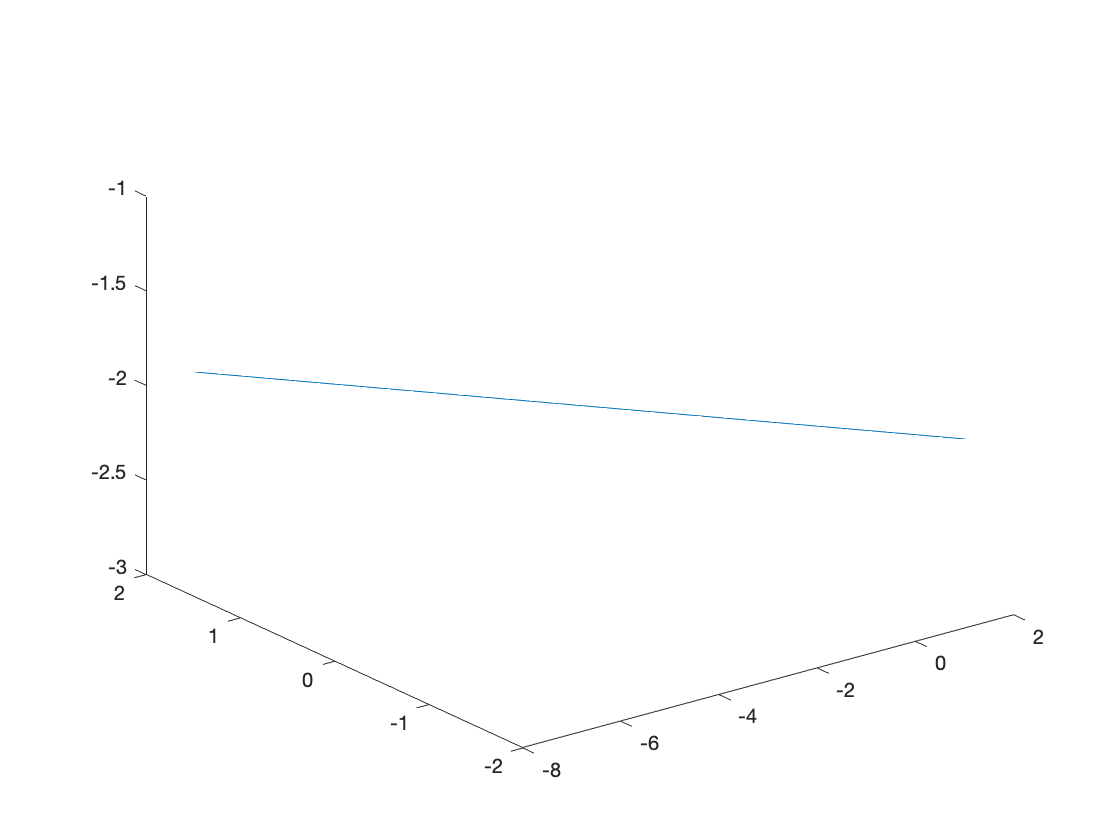

plot3(-2*t-3,t,-2*ones(size(t)))

Thus, every point on this line is a solution of our system. How about the points $(-1,-1,-2)$, $(-3,0,-2)$, and $(-5,1,-2)$ we chose above? Do they lie on this line?

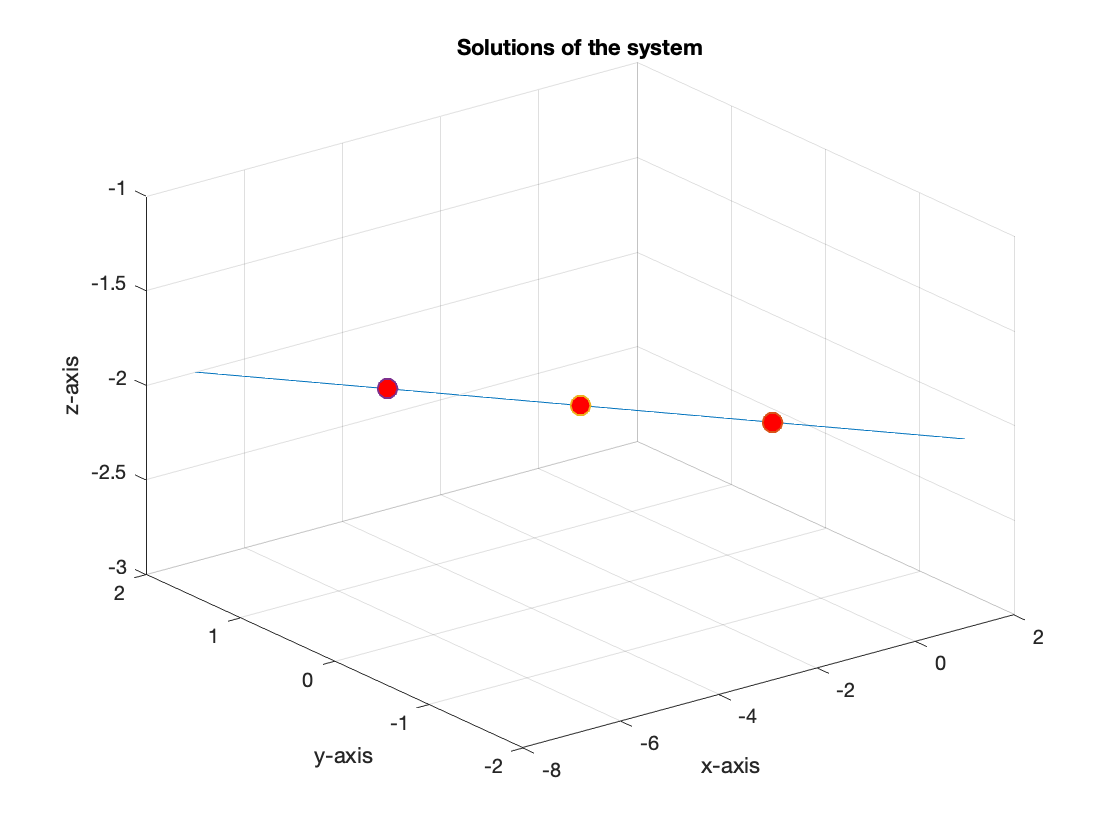

t=linspace(-2,2);
plot3(-2*t-3,t,-2*ones(size(t)))
hold on
plot3(-1,-1,-2,'o','MarkerSize',10,'MarkerFaceColor','r')
plot3(-3,0,-2,'o','MarkerSize',10,'MarkerFaceColor','r')
plot3(-5,1,-2,'o','MarkerSize',10,'MarkerFaceColor','r')
grid on
axis([-8,2,-2,2,-3,-1]) % chosen after a first view
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
title('Solutions of the system')
hold off

They do! :-)

# Example #3:

Solve the following system for $x_1$, $x_2$, $x_3$, and $x_4$.


$$\begin{array}{rcl}
x_1+x_2+x_4&=&3\\
x_1+2x_2+x_3&=&1\\
x_2+x_3-x_4&=&-2
\end{array}$$


Note that we are using subscripts on our variables in this problem. This is common symbolism when the number of variables begins to increase.

**Solution:** Let's rewrite the system a bit to make sure we create the proper augmented matrix.


$$\begin{array}{rcl}
1x_1+1x_2+0x_3+1x_4&=&3\\
1x_1+2x_2+1x_3+0x_4&=&1\\
0x_1+1x_2+1x_3-1x_4&=&-2
\end{array}$$


Although this extra manipulation is not required, some will find it useful to avoid mistakes. Now, the augmented matrix and we highlight the leading entry in row one.


$$\pmatrix{[1]&1&0&1&3\cr 1 & 2 & 1 & 0 &1\cr 0&1&1&-1&-2}$$


Now, we zero out the entries in the first column below our highlighted leading entry.


$$\pmatrix{[1]&1&0&1&3\cr 1 & 2 & 1 & 0 &1\cr 0&1&1&-1&-2}\ \matrix{~\cr R_2-R_1\cr ~}\qquad\longrightarrow\qquad \pmatrix{[1]&1&0&1&3\cr 0& 1 & 1 & -1 &-2\cr 0&1&1&-1&-2}$$


We can check this step with Matlab.

A=[1 1 0 1 3;1 2 1 0 1;0 1 1 -1 -2];
r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2-r1;r3]

A =      1     1     0     1     3
     0     1     1    -1    -2
     0     1     1    -1    -2


We are correct thus far. Now we highlight the leading entry in row two and use it to zero out the entries below it.


$$\pmatrix{[1]&1&0&1&3\cr 0& 1 & 1 & -1 &-2\cr 0&[1]&1&-1&-2}\ \matrix{~\cr ~\cr R_3-R_2}\qquad\longrightarrow\qquad \pmatrix{1&1&0&1&3\cr 0& 1 & 1 & -1 &-2\cr 0 &0 & 0 & 0 & 0}$$


We can check this step with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2;r3-r2]

A =      1     1     0     1     3
     0     1     1    -1    -2
     0     0     0     0     0


Correct! Now we start the backward process, highlighting the leading entry in row two and using it to zero out the entries in the column above it.


$$\pmatrix{1&1&0&1&3\cr 0& [1] & 1 & -1 &-2\cr 0 &0 & 0 & 0 & 0}\ \matrix{R_1-R_2\cr ~\cr ~}\qquad\longrightarrow\qquad \pmatrix{1&0&-1&2&5\cr 0& 1 & 1 & -1 &-2\cr 0 &0 & 0 & 0 & 0}$$


We can check this step with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1-r2;r2;r3]

A =      1     0    -1     2     5
     0     1     1    -1    -2
     0     0     0     0     0


Correct. Now we will highlight our pivots and add some labels to interpret our columns.


$$\begin{array}{c}
\matrix{x_1 & x_2 & \,\,x_3 &\, x_4 & ~~~}\\
\pmatrix{[1]&0&-1&2&5\cr 0& [1] & 1 & -1 &-2\cr 0 &0 & 0 & 0 & 0}\\
\matrix{p & ~p &\ f &\ f & ~~}
\end{array}$$


This shows us that $x_1$ and $x_2$ are pivot variables and $x_3$ and $x_4$ are free variables. Let's write the equations represented by this matrix. Note that the third row represents $0x_1+0x_2+0x_3+0x_4=0$ which is satisfied by any values of $x_1$, $x_2$, $x_3$, and $x_4$, so we have no need to list that one.


$$\begin{array}{rcl}
x_1-x_3+2x_4&=&5\\
x_2+x_3-x_4&=&-2
\end{array}$$


Now, the rule is to solve the equations for the pivot variables $x_1$ and $x_2$ in terms of the free variables $x_3$ and $x_4$.


$$\begin{array}{rcl}
x_1&=&x_3-2x_4+5\\
x_2&=&-x_3+x_4-2\\
x_3&=&\text{free}\\
x_4&=&\text{free}\\
\end{array}$$


If we let $s=x_3$ and $t=x_4$, this can be written as:


$$\begin{array}{rcl}
x_1&=&s-2t+5\\
x_2&=&-s+t-2\\
x_3&=&s\\
x_4&=&t\\
\end{array}$$


Thus, our final answer is


$$(x_1,x_2,x_3,x_4)=(s-2t+5,-s+t-2,s,t)$$


where $s$ and $t$ are free to be any number at all. Let's substitute a few values of $s$ and $t$ and see if this works.


$$s=-1\text{ and }t=-1\qquad\longrightarrow\qquad (x_1,x_2,x_3,x_4)=(6,-2,-1,-1)$$



$$s=0\text{ and }t=0\qquad\longrightarrow\qquad (x_1,x_2,x_3,x_4)=(5,-2,0,0)$$



$$s=1\text{ and }t=1\qquad\longrightarrow\qquad (x_1,x_2,x_3,x_4)=(4,-2,1,1)$$


Let's use Matlab to see if each of these checks. Recall that our original system is:


$$\begin{array}{rcl}
x_1+x_2+x_4&=&3\\
x_1+2x_2+x_3&=&1\\
x_2+x_3-x_4&=&-2
\end{array}$$


x1=6;x2=-2;x3=-1;x4=-1;
[x1+x2+x4;x1+2*x2+x3;x2+x3-x4]

ans =      3
     1
    -2


Checks. 

x1=4;x2=-2;x3=1;x4=1;
[x1+x2+x4;x1+2*x2+x3;x2+x3-x4]

ans =      3
     1
    -2


Checks.

x1=6;x2=-2;x3=-1;x4=-1;
[x1+x2+x4;x1+2*x2+x3;x2+x3-x4]

ans =      3
     1
    -2


Checks! 